# MA431 - Project 4

## Model the following system by using a second order DE

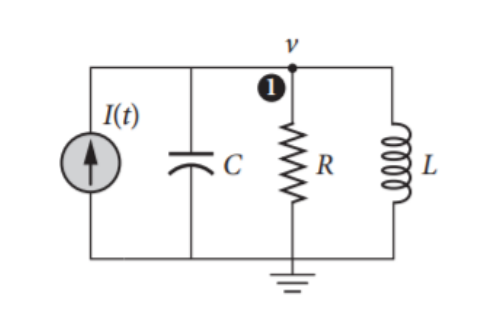

#### 1. Assign some realistic values to the system's parameters, provide references for them.

clc; clear all; close all;
L = 142*10^-3; % H
C = 160*10^-6; % F
R = 1000; % Ohm

syms iL s iLDot
I = 1/s^3

$$I = \frac{1}{s^{3}}$$

eq = iL == ((I)/(L*C))/(s^2 + s/(R*C) + 1/(L*C))

$$eq = \mathrm{iL}=\frac{18446744073709551616}{419110025354681\,s^{3}\,\left(s^{2}+\frac{25\,s}{4}+\frac{6049249712676057}{137438953472}\right)}$$

ilaplace(eq)

$$ans = \mathrm{iL}\,\delta (t)=\frac{2105985160477237221745925791034880210946961517287003127808\,{\mathrm{e}}^{-\frac{25\,t}{8}}\,\left(\cos\left(\frac{\sqrt{2}\,\sqrt{6047907535396057}\,t}{524288}\right)+\frac{14862238047361573683200\,\sqrt{2}\,\sqrt{6047907535396057}\,\sin\left(\frac{\sqrt{2}\,\sqrt{6047907535396057}\,t}{524288}\right)}{36552833464443760303814896267249}\right)}{92775346944235086921536681386110533523183297912255531247370433}-\frac{2177807148294006166165597487563316553318400\,t}{15336670058408497019218307997133787667577942569}+\frac{1267650600228229401496703205376\,t^{2}}{2535301200456459003513081572817}-\frac{2105985160477237221745925791034880210946961517287003127808}{92775346944235086921536681386110533523183297912255531247370433}$$

iL = vpa(ilaplace(eq))

$$iL = \mathrm{iL}\,\delta (t)=0.000022699835999999995722800131559392\,{\mathrm{e}}^{-3.125\,t}\,\left(\cos\left(209.77206411255588905521975614276\,t\right)+0.044717831432460038848456754171104\,\sin\left(209.77206411255588905521975614276\,t\right)\right)-0.00014199999999999997322995143766989\,t+0.49999999999999996045446688425754\,t^{2}-0.000022699835999999995722800131559392$$


eq2 = iLDot == diff(iL)

$$eq2 = \mathrm{iLDot}=\left(\mathrm{iL}\,\delta^{\prime }(t)=0.99999999999999992090893376851509\,t+0.000022699835999999995722800131559392\,{\mathrm{e}}^{-3.125\,t}\,\left(9.3805518022244742202629474137089\,\cos\left(209.77206411255588905521975614276\,t\right)-209.77206411255588905521975614276\,\sin\left(209.77206411255588905521975614276\,t\right)\right)-0.0000709369874999999866337504111231\,{\mathrm{e}}^{-3.125\,t}\,\left(\cos\left(209.77206411255588905521975614276\,t\right)+0.044717831432460038848456754171104\,\sin\left(209.77206411255588905521975614276\,t\right)\right)-0.00014199999999999997322995143766989\right)$$

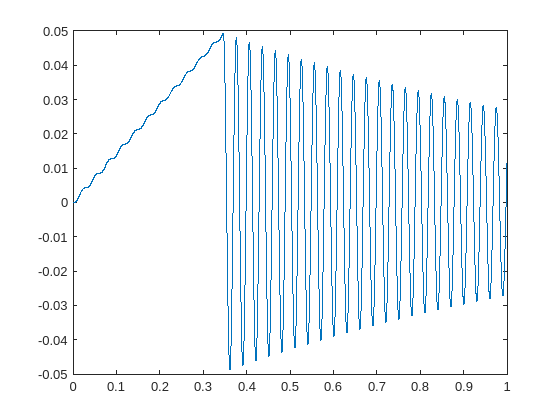


t = 0;
dt = 10^-4;
simTime = 1;
idx = 1;
U = 0;
iL = 0;
while(t <= simTime)
     I = 1/2*t^2;
%     iL = (2.2699836e-5*cos(209.7720641*t))/(2.718281828^(3.125*t)) + (1.01508744e-6*sin(209.7720641*t))/(2.718281828^(3.125*t))+0.5*t^2-1.42e-4*t-2.2699836e-5;
%     iLDot = (0.99999999999999992090893376851509*t + 0.000022699835999999995722800131559392*exp((-3.125*t))*(9.3805518022244742202629474137089*cos(209.77206411255588905521975614276*t) - 209.77206411255588905521975614276*sin(209.77206411255588905521975614276*t)) - 0.0000709369874999999866337504111231*exp((-3.125*t))*(cos(209.77206411255588905521975614276*t) + 0.044717831432460038848456754171104*sin(209.77206411255588905521975614276*t)) - 0.00014199999999999997322995143766989);
%     U = iLDot*L;
if (I > 0.06)
    I = 0.06;
end
    iLDot = 1/L * U;
    uDot = 1/C * (I-iL-U/R);
    t_plt(idx) = t;
    iL_plt(idx) = iL;
    U_plt(idx) = U;

    U = U + uDot * dt;
    iL = iL + iLDot*dt;
    t_plt(idx) = t;
    iL_plt(idx) = iL;
    U_plt(idx) = U;

    t = t + dt;
    idx = idx + 1;

end

plot(t_plt, U_plt)

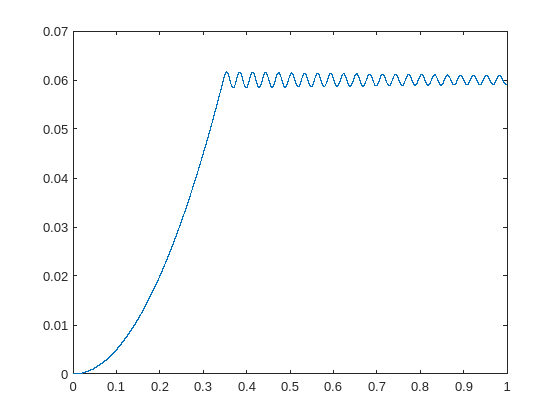


plot(t_plt,iL_plt)


fig = figure;
plot(t_plt,iL_plt, 'b', 'LineWidth', 2)
title("Current in Inductor", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Ampere [A]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("$i_L(t)$", 'Interpreter', 'latex')
grid
filename = "numerical_current_inductor.eps"

filename = "numerical_current_inductor.eps"

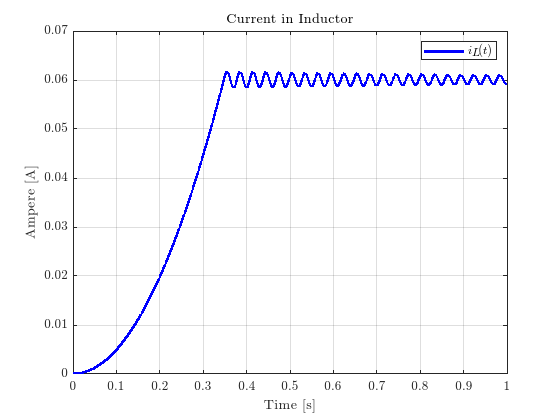

saveas(fig,filename, 'epsc')



fig = figure;
plot(t_plt, U_plt, 'r', 'LineWidth', 2)
title("Voltage of Capacitor", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Ampere [A]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("$i_L(t)$", 'Interpreter', 'latex')
grid
filename = "numerical_voltage_capacitor.eps"

filename = "numerical_voltage_capacitor.eps"

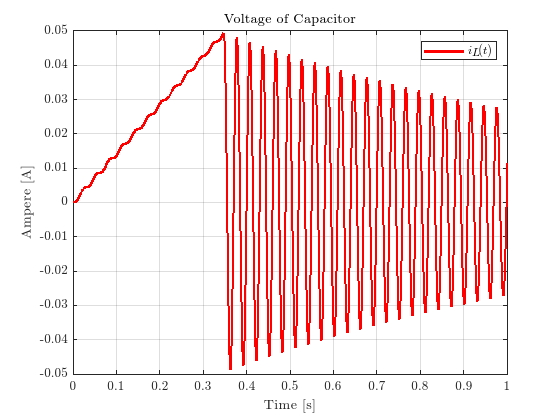

saveas(fig,filename, 'epsc')